Matthew Skipworth

8 October, 2018

TCES 455: Homework 2

1.)

*Work Example Problem E2.21 from Dorf and Bishop. Use *$b_d = 0.65,\ b_s=0.9,\ k_d=1.8,$ and mc = 1 (assume all units, whatever they are, are consistant).  

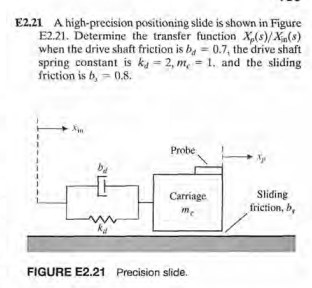

To solve this problem, we will use the laplace transform of each impedance, add them up, set them equal to $X_p
$, then divide the sum by $X_{in}$. The laplace transforms we used from lecture are:


$$k_d \leftrightarrow k*x(s)(spring)\\ 
f_v \leftrightarrow s*f_v*x(s)(fluid)\\
m_c \leftrightarrow m*s^2*s(s)(mass)$$


We will use the the mass equation for $m_c$, the spring equation for $k_d$, and the fluid equation for $b_d\ and\  b_s $.

Since $b_d
$ and $k_d$ are both effected by $x_{in} $ and$x_p$ we will multiply them by the difference of $x_{in} $ and$x_p$.

our equation for the system is as follows:


$$m_c*s^2*x_p+b_s*x_p*s+b_d*(x_p-x_{in})*s+k_d*(x_p-x_{in})=0$$


Next we plug the equation into Matlab and derive the transfer function.

syms xp xin kd mc s bs bd

eq1=(((s^2)*mc+bs*s)*xp)+(bd*s+kd)*(xp-xin)==0

$$eq1 = \mathrm{xp}\,\left(\mathrm{mc}\,s^{2}+\mathrm{bs}\,s\right)-\left(\mathrm{xin}-\mathrm{xp}\right)\,\left(\mathrm{kd}+\mathrm{bd}\,s\right)=0$$

eq1=subs(eq1,[bd,bs,kd,mc],[0.65,0.9,1.8,1])

$$eq1 = \mathrm{xp}\,\left(s^{2}+\frac{9\,s}{10}\right)-\left(\frac{13\,s}{20}+\frac{9}{5}\right)\,\left(\mathrm{xin}-\mathrm{xp}\right)=0$$

simplify(solve(eq1,xp)/xin)

$$ans = \frac{13\,s+36}{20\,s^{2}+31\,s+36}$$

num=[13 36];
denum=[20 31 36];
tranf=minreal(tf(num,denum))


tranf =
 
     0.65 s + 1.8
  ------------------
  s^2 + 1.55 s + 1.8
 
Continuous-time transfer function.



2.)

clear

Work Example Problem E2.20 from Dorf and Bishop. The answer is show how this result is obtained.

                         
$$\frac{V_o(s)}{V(s)}=\frac{2(s+1)}{s+2}$$
 

            show how this result is obtained.

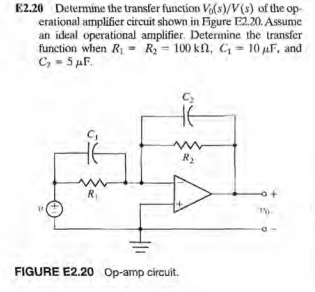

For this problem we assume an ideal Op-Amp. This just means that we can ignore the Op-Amp and place the two parallel combined impedences in series. The equation for combining two impedences in parallel is:


$$z_{eq}=\frac{R_1*R_2}{R_1+R_2}$$


Now we use this equation to combine the parallel impedences. (This makes our circuit easier to work with.)

syms R1 C1 R2 C2 s Vo Vi
z1= ((1/R1)+(s*C1)/1)^(-1);
z2=((1/R2)+(s*C2)/1)^(-1);

Now that we have just the two impedences we see that the circuit resembles a classic inverting amplifier circuit.

The output equation for this kind of circuit is:


$$V_{out}=-V_{in}* \frac{R2}{R1}$$


Vo=Vi*(z2/z1);

Now we divide both sides by the input voltage to derive the transfer function.

H(s) = subs(simplify(Vo/Vi),[R1,R2,C1,C2],[100e3,100e3,10e-6,5e-6])

$$H(s) = \frac{s+1}{\frac{18446744073709553125\,s}{36893488147419103232}+1}$$

num = [1 1];
denum = [18446744073709553125/36893488147419103232 1];
H = minreal(tf(num, denum))


H =
 
  2 s + 2
  -------
   s + 2
 
Continuous-time transfer function.



The transfer function of the system, $H(s)=\frac{2*s+2}{s+2}$

3.)

clear

For the circuit shown below, 

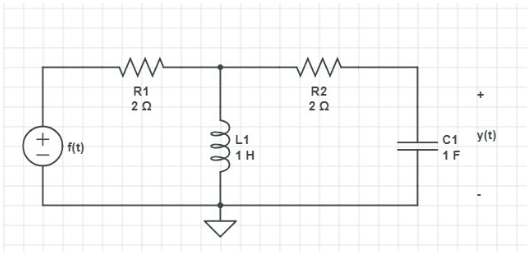

a.)

Find the transfer function from the input f(t) to the  output y(t), i.e., 

find $G(s)= \frac{Y(s)}{F(s)}$

To find a solution for G(s) I used the node voltage technique

syms Vi Vo s R1 R2 v C L t

The equation for the node voltage is:

eq=((Vi-v)/R1)==(v/(s*L))+(v/(2+(1/s)));
v1 = solve(eq,v)

$$v1 = \frac{\mathrm{Vi}}{R_{1}\,\left(\frac{1}{\frac{1}{s}+2}+\frac{1}{R_{1}}+\frac{1}{L\,s}\right)}$$

we then use a voltage divider equation to find the output voltage.

vo=v1*(1/(s*C)/(R2+(1/s*C)))

$$vo = \frac{\mathrm{Vi}}{C\,R_{1}\,s\,\left(R_{2}+\frac{C}{s}\right)\,\left(\frac{1}{\frac{1}{s}+2}+\frac{1}{R_{1}}+\frac{1}{L\,s}\right)}$$

We then divide both sides by the input voltage.

sol = simplify(subs(vo/Vi,[R1, R2, L, C],[2,2,1,1]))

$$sol = \frac{s}{4\,s^{2}+5\,s+2}$$

The transfer function for the system, $H(s)=\frac{s}{4s^2+5s+2}$

num = [1 0];
denum = [4 5 2];
tranf = tf(num,denum)


tranf =
 
         s
  ---------------
  4 s^2 + 5 s + 2
 
Continuous-time transfer function.



b.)

Using partial fraction expansion and the inverse Laplace transform, find y(t) when the input voltage is$f(t)=30e^{-3t}$ volts. Use Matlab to plot the y(t) you found.

To find the ouput, we multiply the laplace transform of the input signal by the transfer function. 

f(t)=30*exp(-3*t);
F(s)=laplace(f(t));
Y(s)=sol*F(s)

$$Y(s) = \frac{30\,s}{\left(s+3\right)\,\left(4\,s^{2}+5\,s+2\right)}$$

num = [30 0];
denum = [4 17 17 6];
H = minreal(tf(num,denum))


H =
 
              7.5 s
  -----------------------------
  s^3 + 4.25 s^2 + 4.25 s + 1.5
 
Continuous-time transfer function.



Y(s)=partfrac(Y(s),'FactorMode','full')

$$Y(s) = -\frac{90}{23\,\left(s+3\right)}-\frac{-\frac{45}{23}+\frac{165\,\sqrt{7}\,\mathrm{i}}{161}}{s+\frac{5}{8}+\frac{\sqrt{7}\,\mathrm{i}}{8}}+\frac{\frac{45}{23}+\frac{165\,\sqrt{7}\,\mathrm{i}}{161}}{s+\frac{5}{8}-\frac{\sqrt{7}\,\mathrm{i}}{8}}$$

y(t)=ilaplace(Y(s))

$$y(t) = -\frac{90\,{\mathrm{e}}^{-3\,t}}{23}+\frac{{\mathrm{e}}^{\frac{t\,\left(-5+\sqrt{7}\,\mathrm{i}\right)}{8}}\,\left(\frac{360}{23}+\frac{1320\,\sqrt{7}\,\mathrm{i}}{161}\right)}{8}-\frac{{\mathrm{e}}^{-\frac{t\,\left(5+\sqrt{7}\,\mathrm{i}\right)}{8}}\,\left(-\frac{360}{23}+\frac{1320\,\sqrt{7}\,\mathrm{i}}{161}\right)}{8}$$

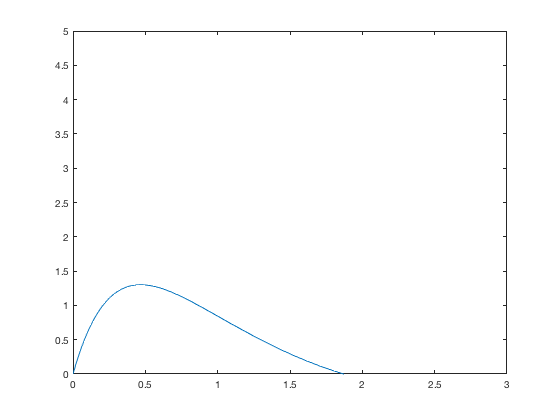

fplot(t, y(t))
xlim([0 3])
ylim([0 5])

c.)

Using Matlab's step() function, plot y(t) for $f(t)=30u(t)$.

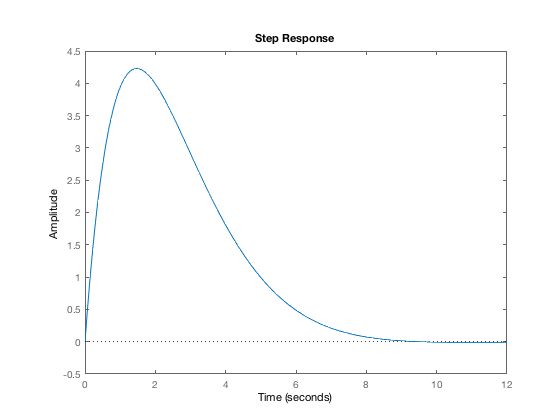

t = 0:.01:5;

step(30*tranf)